% Housekeeping
clc
clear

###  Setup

% All angles in this codebase are always in radians
% au (astronomical unit) is used as the distance unit
% year is used as the time unit

SEC_PER_YEAR = 365.25 * 86400;  % #seconds in a year
AU_km = 149597870.7;            % 1 astronomical unit in km
mu = 39.4769;                   % gravitational parameter of sun

% From problem statement
r0 = [-1.05, 0.0, 0.0];
v0 = [0.0, -6.1316, 0.0];

% converted to au/year^2
at0 = (1/3)*(10^(-7)) * (SEC_PER_YEAR^2) / (AU_km);

state0 = [r0, v0];              % Initial Conditions
tf = 20.0;                      % Mission Duration 

### Part a)

tspan = [0 tf];                             % Mission Time
opts = odeset('RelTol',1e-8,'AbsTol',1e-8); % Tolerance Settings
% Solving 2nd Order ODE using Cowell's Method
[t_cowell,state_cowell] = ode45(@(t,y) perturbed_motion_eq(t,y, at0, mu), tspan, state0, opts);

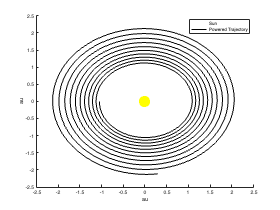

% Plotting
figure()
scatter(0,0,500,"filled","yellow")
hold on
plot(state_cowell(:,1), state_cowell(:,2), 'k')
hold off
xlabel('au')
ylabel('au')
legend('Sun','Powered Trajectory')


disp("Final State:")

Final State:


disp(state_cowell(end,:))

    0.2910   -2.1152         0    4.3013    0.5337         0



### Part b)

% Reseting Enck State to Initial Conditions
state_enck = state0;
state_list_enck = [state_enck];

% Rectification Timestep
rectification_dt = 0.025;

rectify_tspan = [0, rectification_dt];
encke_tspan = rectification_dt:rectification_dt:tf; % Used for performing final integration step

for time = encke_tspan

    orb_ele = cartState2OrbEle(state_enck, mu);
    theta0 = orb_ele(end);

    % Convert from Delta_Time to Delta_Anomaly
    deltaAnomaly = dTime2dAnomaly(state_enck, rectification_dt, theta0, mu); 

    [f, g, f_dot, g_dot] = lagrange_coef(state_enck, deltaAnomaly, mu, (theta0+deltaAnomaly), orb_ele(2));

    % Unperturbed pos and vel
    r_unperturbed = f*state_enck(1:3) + g*state_enck(4:end);
    v_unperturbed = f_dot*state_enck(1:3) + g_dot*state_enck(4:end);
    
    % Initialize pos and vel perturbations
    pertburb_state0 = [0,0,0,0,0,0];

    % Integrate perturbations
    [t, delta_state] = ode45(@(t,y) perturb_enck(t,y, at0, state_enck, mu), rectify_tspan, pertburb_state0, opts);
    r_perturbed = delta_state(end, 1:3);
    v_perturbed = delta_state(end, 4:end);

    % New state composed of osculating and perturbation component
    state_enck = [(r_unperturbed+r_perturbed), (v_unperturbed+v_perturbed)];
    state_list_enck = [state_list_enck; state_enck];
end

% If haven't reached 20 years due to choice of rectification dt, performs a
% last small step to reach 20 years
if encke_tspan(end) ~= 20.0

    final_dt = 20.0-encke_tspan(end); % Just enough to reach 20 years

    orb_ele = cartState2OrbEle(state_enck, mu);
    theta0 = orb_ele(end);

    deltaAnomaly = dTime2dAnomaly(state_enck, final_dt, theta0, mu);

    [f, g, f_dot, g_dot] = lagrange_coef(state_enck, deltaAnomaly, mu, (theta0+deltaAnomaly), orb_ele(2));

    r_unperturbed = f*state_enck(1:3) + g*state_enck(4:end);
    v_unperturbed = f_dot*state_enck(1:3) + g_dot*state_enck(4:end);

    pertburb_state0 = [0,0,0,0,0,0];
    
    [t, delta_state] = ode45(@(t,y) perturb_enck(t,y, at0, state_enck, mu), [0,final_dt], pertburb_state0, opts);
    r_perturbed = delta_state(end, 1:3);
    v_perturbed = delta_state(end, 4:end);
    
    state_enck = [(r_unperturbed+r_perturbed), (v_unperturbed+v_perturbed)];
    state_list_enck = [state_list_enck; state_enck];
end

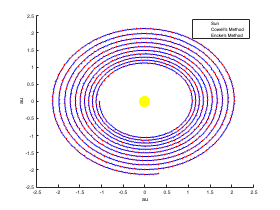

% Plotting
figure()
scatter(0,0,500,"filled","yellow")
hold on
plot(state_cowell(:,1), state_cowell(:,2), 'b', LineWidth=2)
plot(state_list_enck(:,1), state_list_enck(:,2), 'ro', MarkerSize=3, MarkerFaceColor='r')
hold off
xlabel('au')
ylabel('au')
legend('Sun', "Cowell's Method", "Encke's Method")


end_diff = abs(state_cowell(end,:) - state_list_enck(end,:));
relative_end_diff_percent = (norm(end_diff)/norm(state_cowell(end,:))) * 100;
disp(sprintf("The relative difference in state from using Cowell's Method and Encke's Method is: %.2f%%", relative_end_diff_percent))

The relative difference in state from using Cowell's Method and Encke's Method is: 0.81%


### Part c)

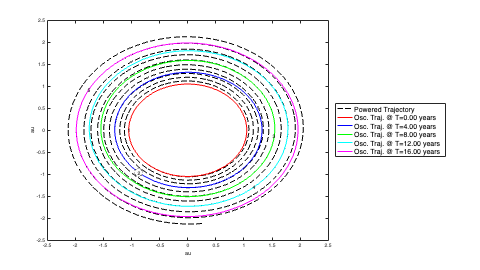

t_orbits = [0:4:16]; % Timesteps at which we are plotting the osculating orbits
color = ['r' , 'b', 'g', 'c', 'm']; % Color pallete

% Angles for plotting ellipse
t_range = linspace(0, 2*pi, 1000);

fig3_legends = ["Powered Trajectory"];

% Plotting starts here
figure()
plot(state_cowell(:,1), state_cowell(:,2), 'k', LineWidth=1, LineStyle='--')
hold on

for t = 1:length(t_orbits)
    % Getting spacecraft state at chosen timesteps
    % from Cowell's integration
    [~,closestIndex] = min(abs(t_cowell-t_orbits(t)));
    state_osc = state_cowell(closestIndex,:);

    % Getting orbital elements
    new_orb = cartState2OrbEle(state_osc, mu);
    a = new_orb(1);
    e = new_orb(2);
    b = a*sqrt(1-e^2);
    TA = new_orb(end); % Angle between perigee of osculating orbit and spacecraft's location

    % Calculating angle between point of interest (that which we use to
    % calculate the osculating orbit) and the +x axis
    if state_osc(2) >= 0
        if state_osc(1) >= 0    % I quadrant
            point_interest_angle = atan(state_osc(2)/state_osc(1));
        else                    % II quadrant
            point_interest_angle = pi + atan(state_osc(2)/state_osc(1));
        end
    else
        if state_osc(1) >= 0    % IV quadrant
            point_interest_angle = 2*pi + atan(state_osc(2)/state_osc(1));
        else                    % III quadrant
            point_interest_angle = pi + atan(state_osc(2)/state_osc(1));
        end
    end

    % Translating ellipse so occupied focus is at (0,0) (Sun's location in
    % a Sun-centred frame of reference)
    x = -a*e + a*sin(t_range);
    y = b*cos(t_range);

    % Rotating ellipse CCW
    rot_matrix = [cos(point_interest_angle-TA), sin(point_interest_angle-TA); -sin(point_interest_angle-TA), cos(point_interest_angle-TA)];
    rotated_xy = [x;y]' * rot_matrix;

    % Plotting rotated ellipse (osculating orbit)
    plot(rotated_xy(:,1), rotated_xy(:,2), color(t), LineWidth=1)
 
    % Plotting (rx,ry) of selected timesteps
    plot(state_osc(1), state_osc(2), 'ok', 'MarkerSize', 16, MarkerFaceColor='white')
    strValues = strtrim(cellstr(num2str(t)));
    text(state_osc(1), state_osc(2),strValues, 'HorizontalAlignment','center', 'VerticalAlignment','middle', 'fontsize', 10);
    fig3_legends = [fig3_legends, sprintf('Osc. Traj. @ T=%.2f years',t_cowell(closestIndex)), ""];
end

hold off
lgd = legend(fig3_legends,"Location","eastoutside");
lgd.FontSize = 14;
set(gcf,'position',[0,0,960,540])
xlabel('au')
ylabel('au')

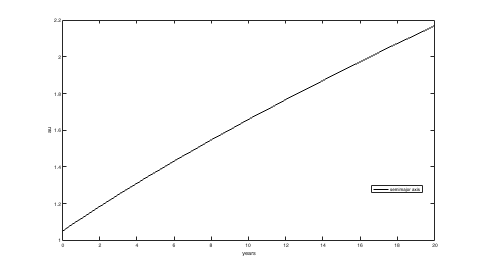

% Extra Plots
a_list = [];
e_list = [];

% Getting variations of a,e along the mission
for idx = 1:length(t_cowell)
    state_osc = state_cowell(idx,:);
    orb_ele = cartState2OrbEle(state_osc, mu);
    a_list = [a_list; orb_ele(1)];
    e_list = [e_list; orb_ele(2)];
end

figure()
plot(t_cowell, a_list, 'k')
set(gcf,'position',[0,0,960,540])
xlabel("years")
ylabel("au")
legend("semimajor axis", Location="best")

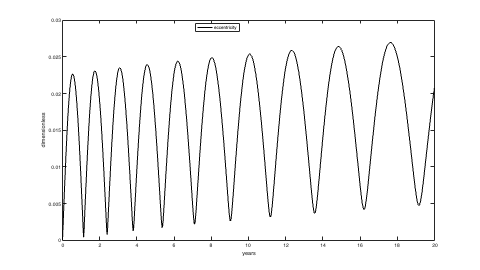


plot(t_cowell, e_list,'k')
set(gcf,'position',[0,0,960,540])
xlabel("years")
ylabel("dimensionless")
legend("eccentricity", Location="best")

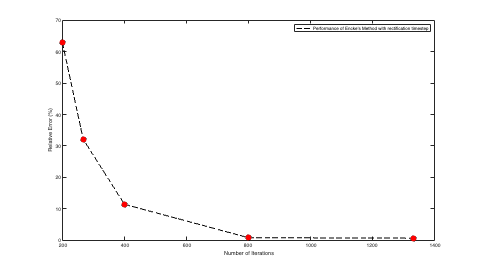

% Elbow Method analyis for rect timestep
% Data was collected by running the Part 2 codeblock with different
% rectifying timestep values
tested_dt = [0.1, 0.075, 0.05, 0.0250, 0.0150];                     % in years
relative_err_percent = [62.7786, 32.1545, 11.4287,0.8126, 0.6688];  % in percent

figure()
plot(20./tested_dt, relative_err_percent, 'ko--',MarkerSize=12, MarkerFaceColor='r')
legend("Performance of Encke's Method with rectification timestep")
set(gcf,'position',[0,0,960,540])
xlabel("Number of Iterations")
ylabel("Relative Error (%)")

function at = get_at(state, at0)
    % State: r,v of the spacecraft (6,1)
    % at0: magnitude of acceleration at 1 au (1,1)
    r = state(1:3);
    v = state(4:end);

    dist = norm(r);
    unit_v = v/norm(v);

    at = at0 * unit_v * ((1/dist)^2);
end

function dstate_dt = perturbed_motion_eq(t, y, at0, mu)
    % y: r,v of the spacecraft (6,1)
    % at0: magnitude of acceleration at 1 au (1,1)
    % mu: gravitational parameter of Sun (1,1)
    drdt = y(4:end);

    at = get_at(y, at0);

    dist = norm(y(1:3));

    dvdt = -mu*(y(1:3)/(dist^3)) + at;
    
    dstate_dt = [drdt; dvdt];
end


function dstate_dt = perturb_enck(t, y, at0, state0, mu)
    % y: delta_r,delta_v of the spacecraft (6,1)
    % at0: magnitude of acceleration at 1 au (1,1)
    % state0: r,v of the spacecraft (6,1)
    % mu: gravitational parameter of Sun (1,1)

    r0 = state0(1:3);
    v0 = state0(4:end);

    per_r = y(1:3).';
    per_v = y(4:end).';

    r0_norm = norm(r0);

    q = dot(per_r, (per_r-2*r0)) / r0_norm;
    
    phi_q = -q*(3+3*q+3*q*q)/(1+(1+q)^(3/2));

    at = get_at([r0, v0], at0);

    dper_v_dt = (-mu/r0_norm^3)*per_r + at + (mu/r0_norm^3)*phi_q*(r0+per_r);
    
    dstate_dt = [per_v, dper_v_dt].';
end


function orb_ele = cartState2OrbEle(state, mu)
    % Algorithm 4.2 from Curtis' Book
    % state: r,v of the spacecraft (6,1)
    % mu: gravitational parameter of Sun (1,1)

    eps = 1.e-10;
    R = state(1:3);
    V = state(4:end);
    r = norm(R);
    v = norm(V);

    vr = dot(R,V)/r;
    
    H = cross(R,V);
    h = norm(H);

    inclination = acos(H(3)/h);

    N = cross([0 0 1], H);
    n = norm(N);

    if n ~= 0
        RAAN = acos(N(1)/n);
        if N(2) < 0
            RAAN = 2*pi - RAAN;
        end
    else
        RAAN = 0;
    end

    E = 1/mu*((v^2-mu/r)*R - r*vr*V);
    e = norm(E);

    if n ~= 0
        if e > eps
            w = acos(dot(N, E)/n/e);
            if E(3) < 0
                w = 2*pi - w;
            end
        else
            w = 0;
        end
    else
        w = 0;
    end

    if e > eps
        TA = acos(dot(E,R)/e/r);
        if vr < 0
            TA = 2*pi - TA;
        end
    else
        cp = cross(N, R);
        if cp(3) >= 0
            TA = acos(dot(N,R)/n/r);
        else
            TA =  2*pi - acos(dot(N,R)/n/r);
        end
    end

    a = h^2/mu/(1-e^2);

    orb_ele = [a, e, inclination, RAAN, w, TA];
end

function [f, g, f_dot, g_dot] = lagrange_coef(state, deltaTheta, mu, theta1, e)
    % state: r,v of the spacecraft (6,1)
    % deltaTheta: change in true anomaly (1,1)
    % mu: gravitational parameter of the Sun (1,1)
    % theta1: true anomaly of the final position (theta1 = theta0 + deltaTheta) (1,1) 
    % e: eccentricity (1,1)

    r = state(1:3);
    v = state(4:end);

    dist = norm(r);

    h = norm(cross(r,v));
    s = sin(deltaTheta);
    c = cos(deltaTheta);

    r = h^2/mu/(1+e*cos(theta1));

    f = 1 - mu*r*(1-c)/h^2;
    g = dist*r*s/h;
    f_dot = mu/h*(1-c)/s*(mu/h^2*(1-c)-1/dist-1/r);
    g_dot = 1-mu*dist/h^2*(1-c);

end


function deltaAnomaly = dTime2dAnomaly(state, delta_Time, theta0, mu)
    % state: r,v of the spacecraft (6,1)
    % delta_Time: time difference (delta_Time = t2-t1) (1,1)
    % theta1: true anomaly of the final position (theta1 = theta0 + deltaTheta) (1,1) 
    % mu: gravitational parameter of the Sun (1,1)

    R = state(1:3);
    V = state(4:end);

    r = norm(R);
    v = norm(V);

    H = cross(R, V);
    h = norm(H);

    a = (-mu)/((v^2) - (2*mu)/r);
    e = sqrt(1-(h^2)/(mu*a));

    E0 = 2*atan(sqrt((1-e)/(1+e))*tan(theta0/2));
    M0 = E0 - e*sin(E0);
    M1 = M0 + sqrt(mu/(a^3))*delta_Time;

    E1_old = 0;
    while true
        E1_new = M1+e*sin(E1_old);
        if abs(E1_old-E1_new) < 1e-8
            break
        end
        E1_old = E1_new;
    end
    theta1 = 2*atan(sqrt((1+e)/(1-e))*tan(E1_new/2) );
    
    deltaAnomaly = theta1-theta0;

end